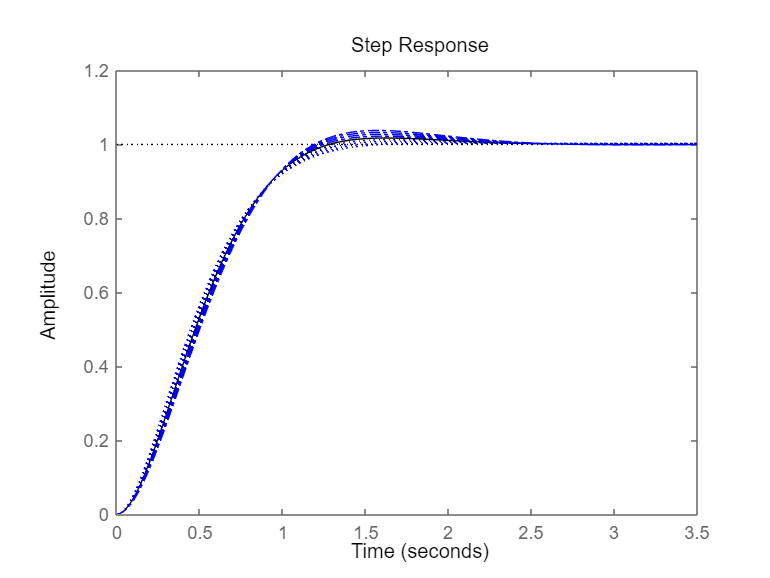

clc;
close all;
clear all;

s = tf('s');


t = (0:0.01:10)';

G1 = 10/(1*s^2+5*s+10);
G2 = 10/(0.8*s^2+5*s+10);
G3 = 10/(0.85*s^2+5*s+10);
G4 = 10/(0.90*s^2+5*s+10);
G5 = 10/(0.95*s^2+5*s+10);

G6 = 10/(1.05*s^2+5*s+10);
G7 = 10/(1.1*s^2+5*s+10);
G8 = 10/(1.15*s^2+5*s+10);
G9 = 10/(1.20*s^2+5*s+10);

figure;step(G2,':',G3,':',G4,':',G5,':',G1,'black-',...
            G6,'-.',G7,'-.',G8,'-.',G9,'-.');

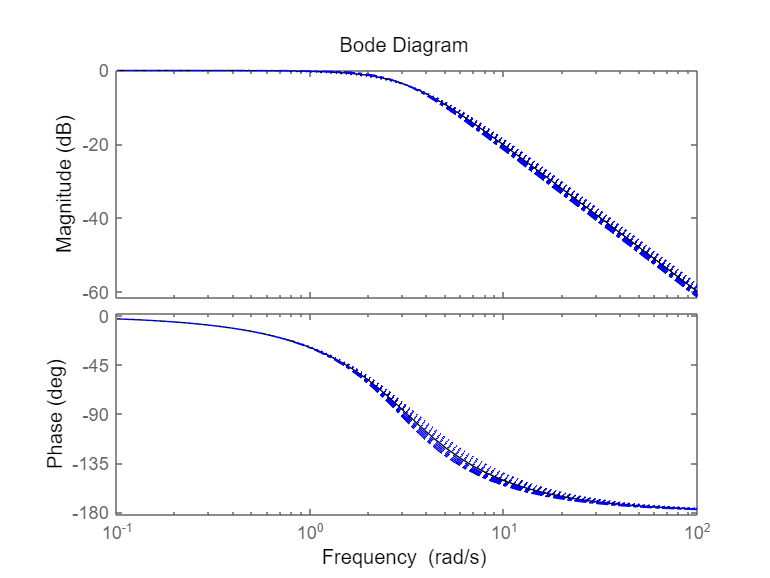

figure;bode(G2,':',G3,':',G4,':',G5,':',G1,'black-', ...
            G6,'-.',G7,'-.',G8,'-.',G9,'-.');

C1=pidtune(G1,'PI')

C1 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.07, Ki = 2.47
 
Continuous-time PI controller in parallel form.



sys1=feedback(G1*C1,1);

C11=pidtune(sys1,'PI')

C11 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.131, Ki = 1.87
 
Continuous-time PI controller in parallel form.



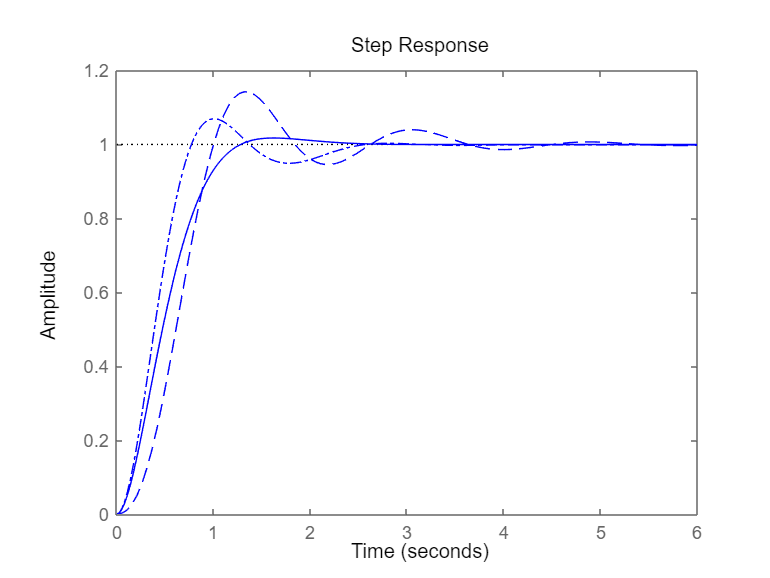

sys11=feedback(sys1*C11,1);
step(G1,'-',sys1,'-.',sys11,'--')